# Neural Networks Fundamentals

The definition of AI coined in the 1950s and still in use is "*the capability of a machine to imitate intelligent human behavior*." When the machine does not just imitate, but match or even exceed human performance, it gives us the opportunity to offload repetitive tasks, or even to get computers to do jobs more safely and efficiently than we can.

Practically speaking, when people think of AI today, they almost always mean *machine learning*: training a machine to learn a desired behavior. In traditional programming, we'd write a program (sequence of operations) that processes input data to produce a desired output.

With machine learning, the steps are reversed: you feed in data and the desired output, and the computer writes the program for you. Machine learning models generate the desired output, but they aren't composed of a sequence of operations like a traditional program or algorithm.

Deep learning is a subset of machine learning, which was inspired by the neural pathways of the human brain. Deep learning uses neural networks - the term "deep" refers to the multiple layers in the network. 

In this live script, we will use the `Perceptron` app, designed in MATLAB® for this workshop, to help illustrate fundamental concepts of neural networks.

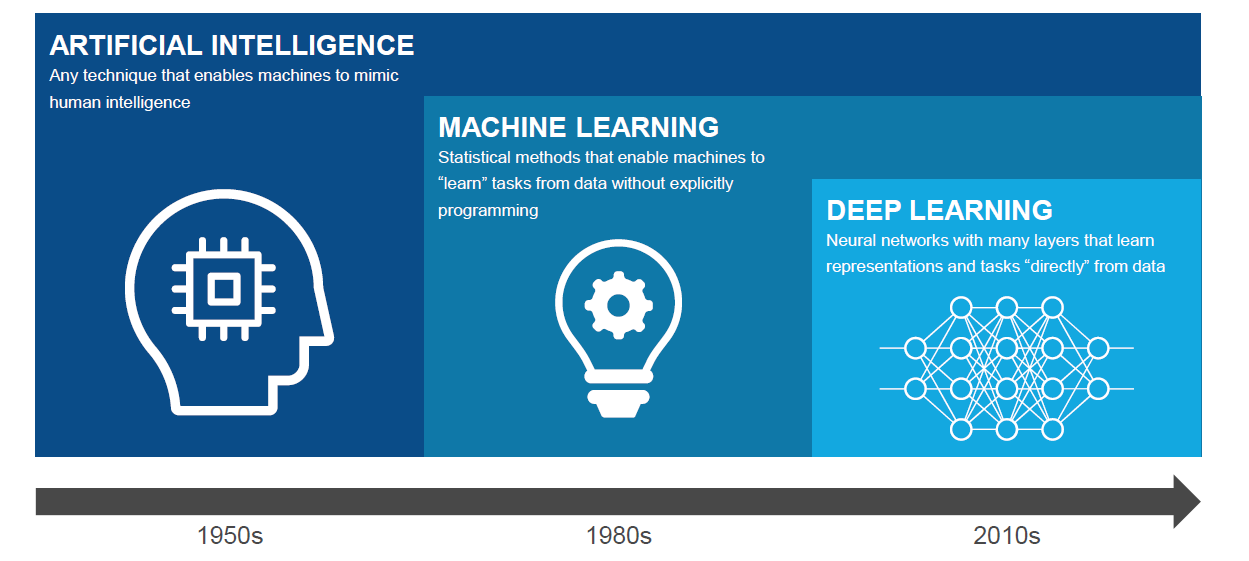

### Single-layer Neural Networks

Artificial neural networks are simplified models of the nervous system.

Thinking of a neuron as a conducting brain cell in the nervous system that receives and transmits electrical signals if the signal is strong enough, a ***perceptron*** is an artificial neuron: a **function** taking one or more **inputs **${\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} ,$ weighing each input separately ${\mathit{\mathbf{w}}}_{\mathit{\mathbf{i}}} {\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}}$, summing up these weighted inputs $\sum_i {\mathit{\mathbf{w}}}_{\mathit{\mathbf{i}}} {\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}}$ and comparing this sum with a certain **threshold **to generate a **binary** **output signal **$\mathit{\mathbf{y}}$ if the accumulated signal exceeds the threshold $\sum_i {\mathit{\mathbf{w}}}_{\mathit{\mathbf{i}}} {\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} +\textrm{bias}\ge 0$. The output is given by the **activation** function, which in this case is the `step` function.

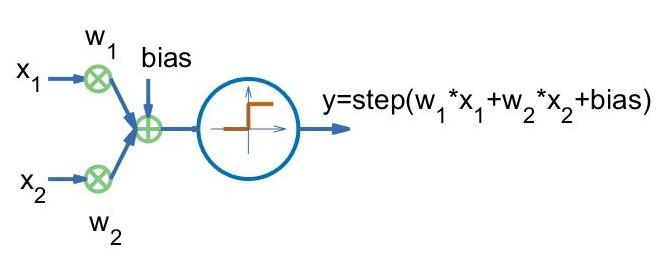

In the figure above, $\mathit{\mathbf{y}}$ maps its two inputs ${\mathit{\mathbf{x}}}_1$and ${\mathit{\mathbf{x}}}_2$ to a binary value depending on how the sum of the two weighted inputs ${\mathit{\mathbf{w}}}_1 {\mathit{\mathbf{x}}}_1 +{\mathit{\mathbf{w}}}_2 {\mathit{\mathbf{x}}}_2$ compares to $-\textrm{bias},$ the neuron activating for values larger than $-\textrm{bias}$:


$$y=\;\left\lbrace \begin{array}{ll}
1 & \textrm{if}\;w_1 x_1 +w_2 x_2 +\textrm{bias}\ge 0,\\
0 & \textrm{otherwise}
\end{array}\right.$$


The neuron's parameters govern its behavior, and can be adjusted so that the perceptron behaves as desired (produces the desired output for known samples - your training data set - and ultimately generalizes to new, unknown samples): 

- *Positive* **weights** ${\mathit{\mathbf{w}}}_{\mathit{\mathbf{i}}}$ act to *excite *incoming signals, while *negative* weights *inhibit* incoming signals. 

- The $\textrm{bias}$ shifts the position of the decision boundary away from the origin. For a zero $\textrm{bias}$, the neuron activates (output is one) for a positive sum and does not activate (output is zero) for a negative sum. 

#### Exercise 

Start the `Perceptron` app:

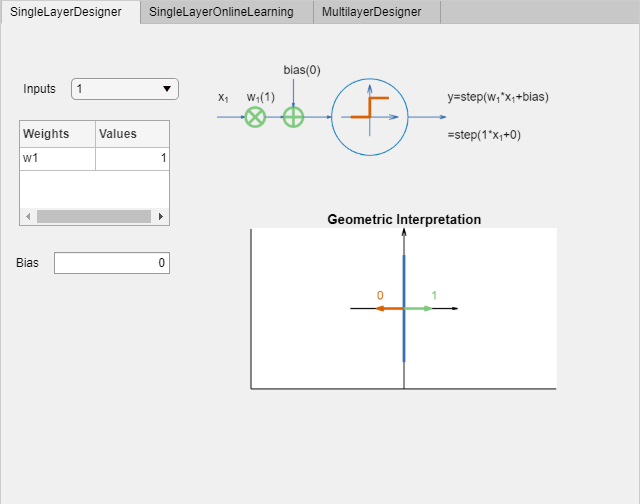

Perceptron

The `SingleLayerDesigner` tab will show by default a single neuron with a single input ${\mathit{\mathbf{x}}}_1$and the following parameters:

- weight $w_1 =1$ 

- 
$$\textrm{bias}=0$$


The top figure on the rhs shows the architecture of the neuron, with 


$$y=\textrm{step}\left(w_1 x_1 +\textrm{bias}\right)=\textrm{step}\left(x_1 \right)=\left\lbrace \begin{array}{ll}
1 & \textrm{if}\;x_1 \ge 0\\
0 & \textrm{otherwise}
\end{array}\right.$$


The bottom figure shows the geometrical interpretation, with the blue line separating the inputs for which the neuron activates (in the direction of the green vector) from those for which the neuron does not activate (in the direction of the orange vector).

**TO DO: **Modify the parameters of the neuron to the following values:

- weight $w_1 =-1$

- $\textrm{bias}=0\ldotp 5$. 

The resulting neuron architecture and interpretation should look like below:

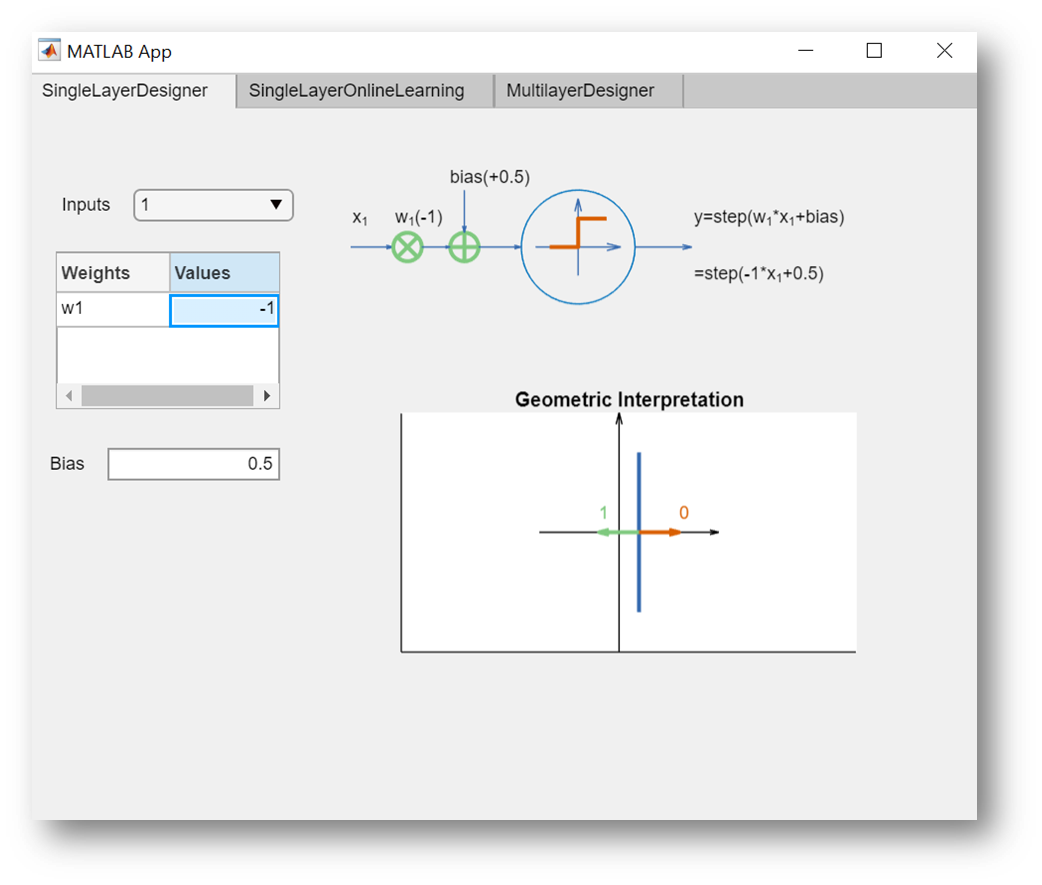

Notice the neuron activates for inputs $x_1 \le \frac{1}{2}$ (the negative weight acts inhibitorily). The table below shows the outputs for binary inputs. If only binary inputs were allowed, then this perceptron would approximate the **negation** function. 

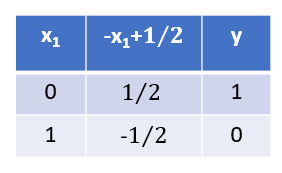

In practice, the parameters (weights and bias) of the perceptron (or of a mathematical model) are not known beforehand. Instead, a machine learning algorithm will learn from a set of known inputs, here $x_1 =\left\lbrace 0,1\right\rbrace$, and expected outputs, here $y=\left\lbrace 1,0\right\rbrace$, what the parameters should be to get the desired output for the given input.

A perceptron is a binary classification algorithm; in the simple case of the negation function with binary inputs, the algorithm is looking for a threshold separating the input values for which the neuron activates (1) from those for which it doesn't (0). The threshold here is $1/2$, but infinitely many other values would have also been possible. We will see later an example of a learning algorithm for the perceptron.

#### Exercise

**TO DO: **Modify the neuron architecture to have two inputs with the following parameters:

- weights $w_1 =3$ and $w_2 =2$

- $\textrm{bias}=-4$. 

The bottom figure shows the geometric interpretation. The equation of the blue separation line is $3{\mathit{\mathbf{x}}}_1 +2{\mathit{\mathbf{x}}}_2 =4$. The neuron activates for all inputs to the right of the line, in the direction of the green vector, which is also the direction of the normal to the line $\overrightarrow{n} =\left(3,2\right)$.

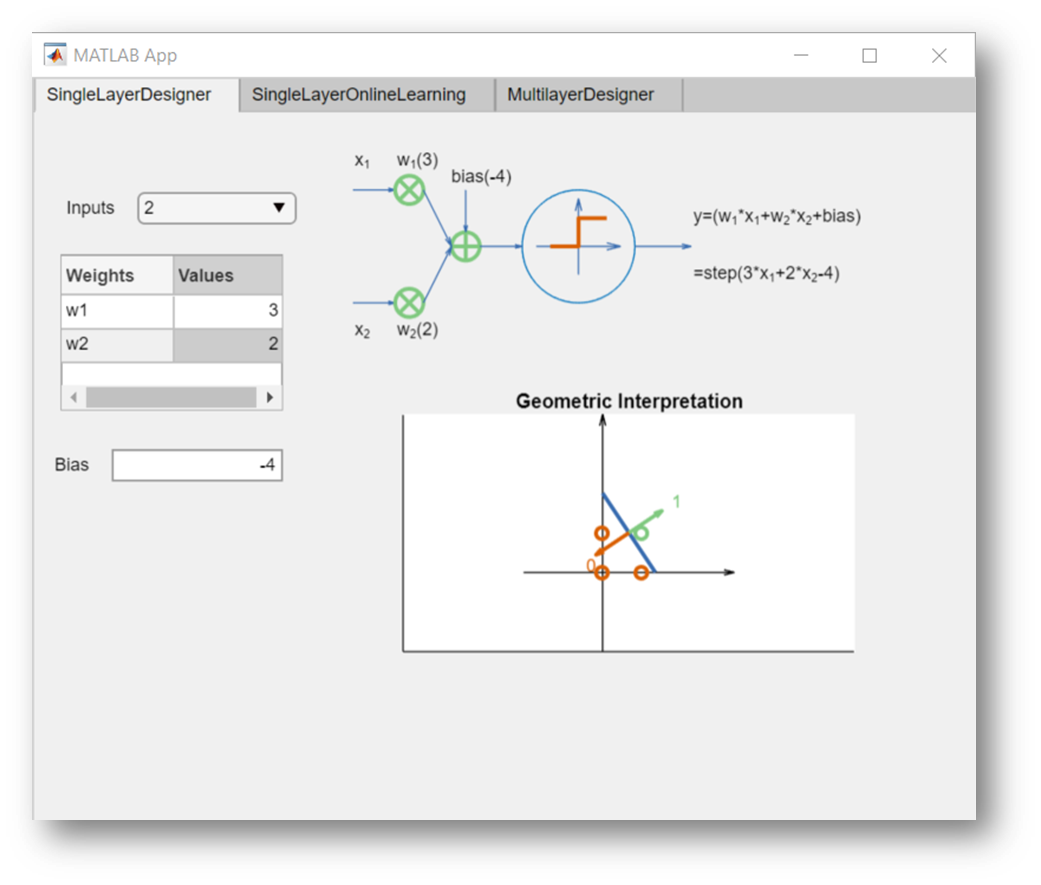

Assuming again only binary inputs (see the table below), the perceptron represents **conjunction (AND)**, the output is one (and marked by a green circle in the figure) only when both inputs are one. The neuron does not activate for the other three inputs (marked by orange circles). 

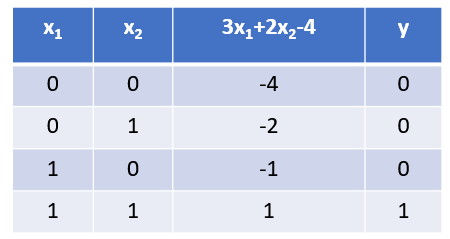

For two inputs, the learning algorithm is looking for a line separating the input values for which the neuron activates from those for which it doesn't. The geometrical interpretation is valid also for three or more inputs, with the separation line becoming a separation plane for three inputs and a hyperplane beyond three inputs. 

For more than three inputs, the geometrical interpretation is difficult to visualize. Furthermore, instead of us assigning parameters explicitly, i.e., the way we did in the previous two exercises, the learning algorithm should be able to *learn* to assign its own parameters based on the available training data set.

### Learning Algorithm

Often the perceptron learns by starting with random parameters$\left(w,\textrm{bias}\right),$ iterating through the training data $\left(x,y\right)$ and updating the parameters $\left(w,\textrm{bias}\right)$ after each set of inputs until the desired function has been learned (in other words, until an error function $e,$ defining the extent to which the actual outputs $o$ differ from the expected outputs $y,$ is zero). 

To start with, we can define the error function as the difference between the expected and the actual output $e=y-o$. 

The goal is to update the parameters $\left(w,\textrm{bias}\right)$ to minimize the error function $e=y-o$. 

Parameters are updated either immediately after each set of inputs (*online learning*) or by aggregating the updates after going through an *epoch*, i.e., through all sets of inputs (*batch learning*):

- If the neuron outputs what we expected ($\left.o=y\right),$ do nothing, because the perceptron classified the input correctly.

- If the neuron activates for input $x$ when it should not (actual output $o=1$ when expected output $y=0$), suppress it (make $w\cdot x+\textrm{bias}$ smaller to get $o=0$ by decreasing $w$ and $\textrm{bias}$). 

- If the neuron does not activate for input $x$ when it should (actual output $o=0$ when expected output $y=1$), excite it (make $w\cdot x+\textrm{bias}$ larger to get $o=1$ by increasing $w$ and $\textrm{bias}$). 

The added/subtracted amount to each parameter is proportional to the error $e=y-o$ and to a learning rate $\alpha ,$ which describes the magnitude of the update, i.e., a higher learning rate will lead to larger changes in the parameters and thus to a faster learning, but it is also more sensitive to noise or to sequences of non-representative training data.

Given that $y$ and $o$ are both binary, only one of the following three values are possible for $e\;$for any input $x$, namely $1$, $-1$ or $0$.

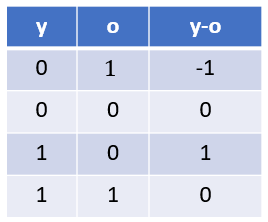

If we consider the $\textrm{bias}$ as a weight $w_0 =\textrm{bias}$ with an associated input $x_0 =1,$ we can summarize the weight update rule as:

${\mathit{\mathbf{w}}}^{\textrm{new}} \;={\mathit{\mathbf{w}}}^{\textrm{old}} +\alpha \cdot \mathit{\mathbf{e}}\cdot \mathit{\mathbf{x}}={\mathit{\mathbf{w}}}^{\textrm{old}} +\alpha \cdot \left(\mathit{\mathbf{y}}-\mathit{\mathbf{o}}\right)\cdot \mathit{\mathbf{x}}$, where $x=1$ for the $\textrm{bias}$.

We can summarize the online training algorithm as follows (note that in this implementation we start with the values in the `SingleLayerDesigner` instead of random weights and bias):

#### Exercise

We will illustrate the learning algorithm on the simple example of a perceptron with one input, learning appropriate parameters to model the binary negation function. To this purpose, we will start the `Perceptron` app, keep the default values in the `SingleLayerDesigner` tab and switch to the `SingleLayerOnlineLearning` tab. 

Perceptron

The `SingleLayerOnlineLearning` tab is populated using the parameters from the `SingleLayerDesigner` tab, and displays, for the given number of inputs, all possible binary inputs and the outputs computed using the parameters. For convenience, we will drop indices.

For a single neuron with a single input $x$ and the following parameters:

- weight $w=1$ 

- 
$$\textrm{bias}=0$$


there are only two possible inputs $\left\lbrace 0,1\right\rbrace$. The computed outputs based on the activation function are $\left\lbrace 1,1\right\rbrace$. For the negation function, the expected outputs for $\left\lbrace 0,1\right\rbrace$should be $\left\lbrace 1,0\right\rbrace$. Correct the second output in the tab; this should look as follows:

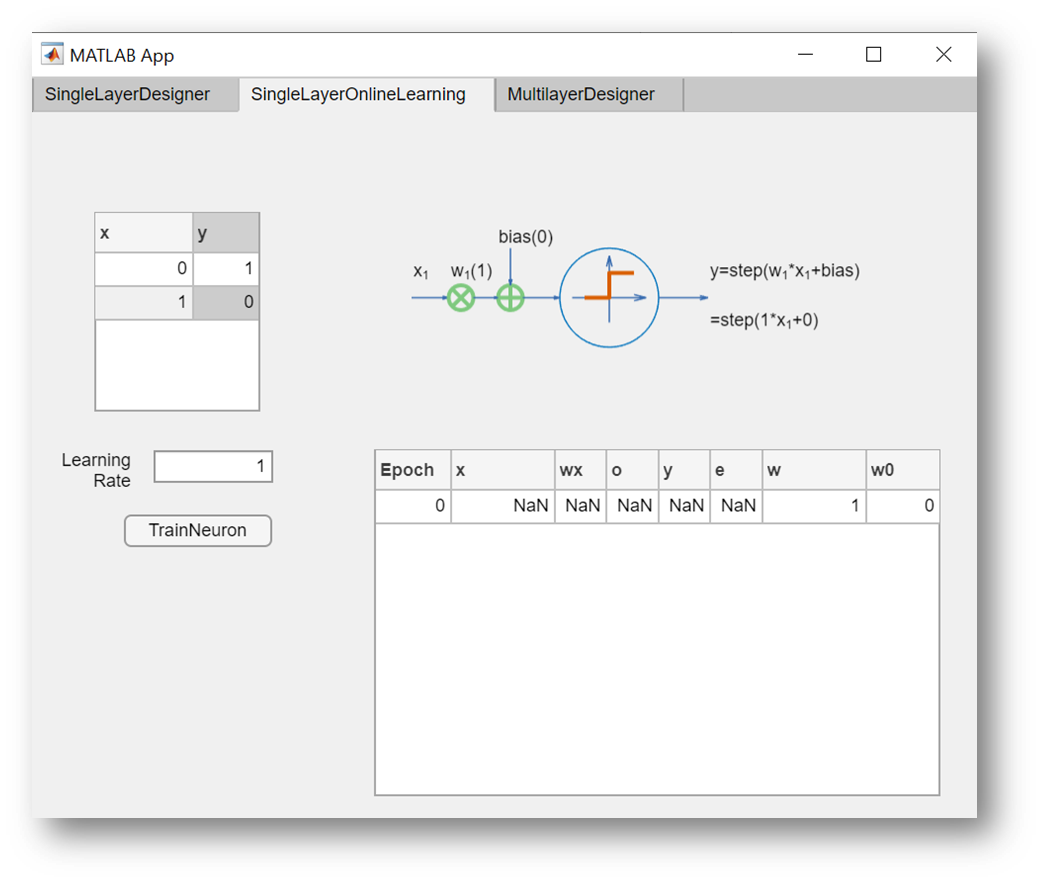

Notice the table in the rhs, which will show the results of the online learning algorithm. Its first row before training (epoch = 0) shows the parameters in its last two columns and otherwise only `NaN`.

**TO DO: **Start the online training by clicking `TrainNeuron`. Once the learning algorithm has converged (the error function $e=0$), the table will show the updates of the parameters for every iteration and every pass through the whole training set (for every epoch).

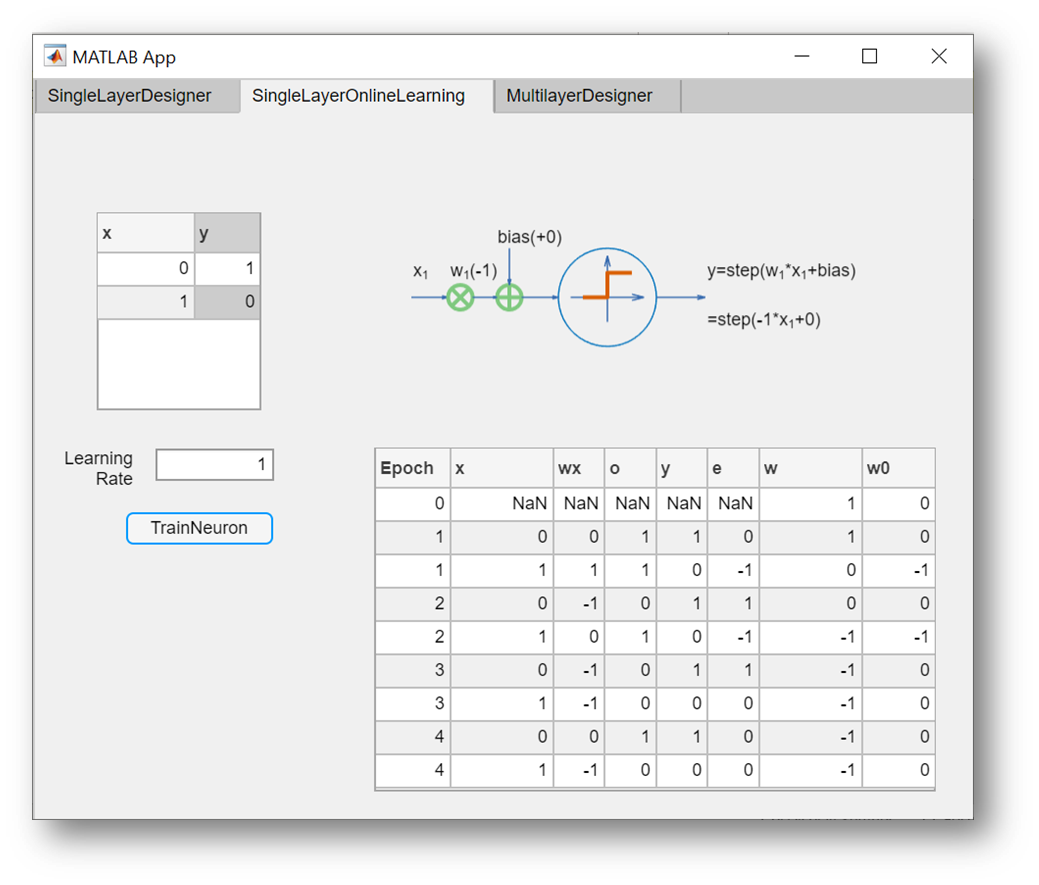

Looking at the first epoch (first pass through the whole data set):

- for input $x=0$ (shown in the second column), the accumulated weighted input $w\cdot x=0\ge 0$ (shown in the third column), so the output $o=1$ (shown in the fourth column) is equal to the desired output $y=1$ (shown in the fifth column). The error (shown in the sixth column) is $e=0$, so the parameters are not modified.

- for input $x=1,$ the positive accumulated weighted input $w\cdot x=1\ge 0$ leads to an actual output $o=1$ when the desired output $y=0$. Both parameters are thus decremented, to reduce the error.

In the second epoch:

- for input $x=0,$ the negative bias leads to an actual output $o=0$ when the desired output $y=1$. The parameters are thus incremented. Notice that only the bias $w_0$ is modified. 

- for input $x=1,$ both parameters are again decremented.

In the third epoch:

-  $x=0$ is misclassified, which results in the bias being incremented, while the weight remains unmodified. 

-  $x=1$ is classified correctly, so the parameters are not modified.

In the fourth epoch, both inputs are classified correctly, so the learning stops. Switching to the `SingleLayerDesigner` tab will show the geometrical interpretation of the negation function:

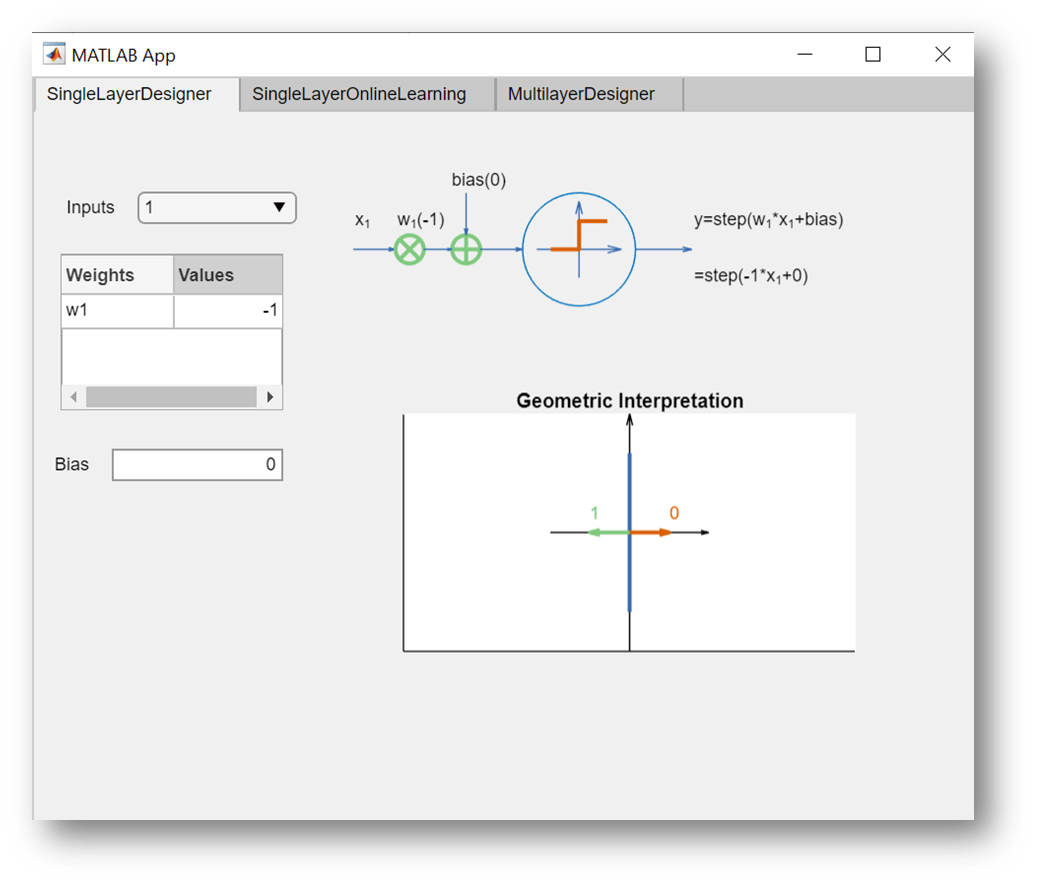 

Notice the learning algorithm converged to the same weight as before, but to a different bias. Starting with different initial parameters can result in different parameters being learned, since there are infinitely many ways of separating the training data.

#### Exercise

We will now see the learning algorithm for a perceptron with two inputs, learning appropriate parameters to compute conjunction. 

**TO DO:** In the `SingleLayerDesigner` tab app, choose two inputs and use the default values. Then switch to the `SingleLayerOnlineLearning` tab and modify the output values to correspond to the conjunction function. Start training.

As the geometric interpretation below shows, the separating line has the equation $2x_1 +x_2 =3$. The conjunction is computed correctly, even if the input $\left(1,1\right)$ lies on the separating line.

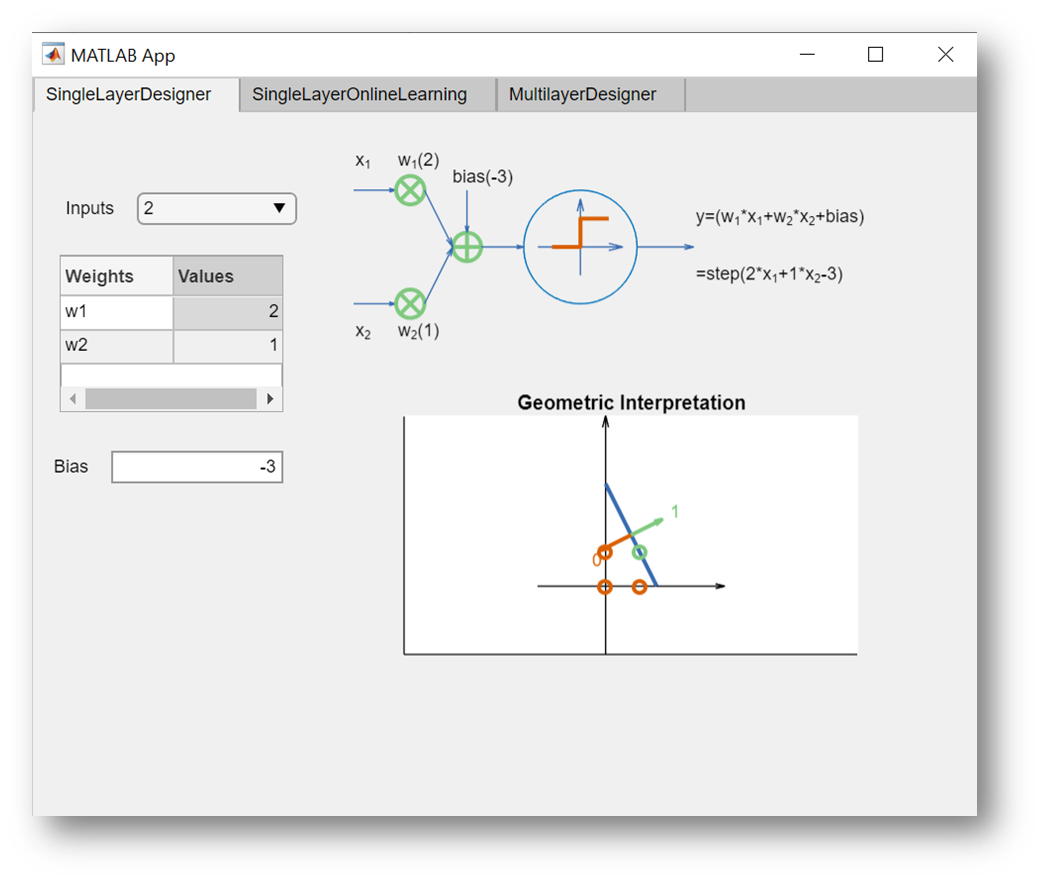

As long as positive examples can be separated by the negative examples **linearly** (by a line, a plane or a hyperplane), the perceptron is guaranteed to converge to an approximate solution. This solution is not unique, since there are infinitely many ways with a varying degree of quality to separate classes of points linearly.   

If the training set is **not linearly separable**, a perceptron will **never** learn the correct parameters to classify all inputs correctly. Take the simple example of the bi-implication function. The second and third epoch are identical and will repeat endlessly, without converging to a solution (we stopped training before the hundredth epoch).

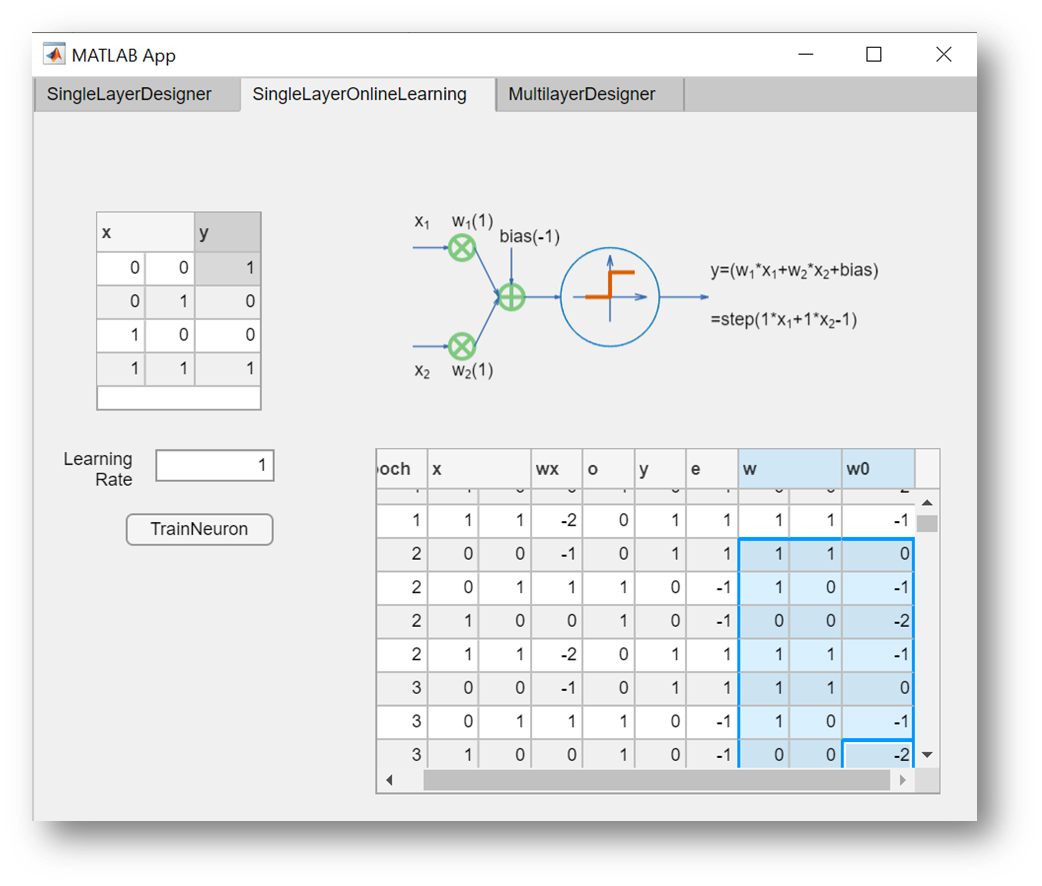

### Multilayer Perceptron

Since a perceptron can only classify correctly training data that is linearly separable, there is only a limited number of problems solvable with a single layer perceptron. For more complex problems, we can break the problem into simpler parts that could each be modelled with only one neuron, and form a complex network with multiple neurons organized into layers passing information among themselves. This is called a **multilayer perceptron**.

For instance, the bi-implication function can be rewritten as the conjunction of two implications $x_{1\;} \leftrightarrow \;x_2 \equiv \left(x_1 \to x_2 \right)\wedge \left(x_2 \to x_1 \right)$, which corresponds to a two-layer network with three neurons:

- two neurons for each implication function in the first layer

- a third neuron for the conjunction in the second layer, whose inputs are the outputs of the two neurons in the previous layer.

If we consider the inputs as a layer in itself, we can solve the bi-implication problem by a three-layer network:

- an input layer 

- a hidden layer (hidden because its state is hidden), with two neurons solving the two implication functions

- an output layer, solving the conjunction.

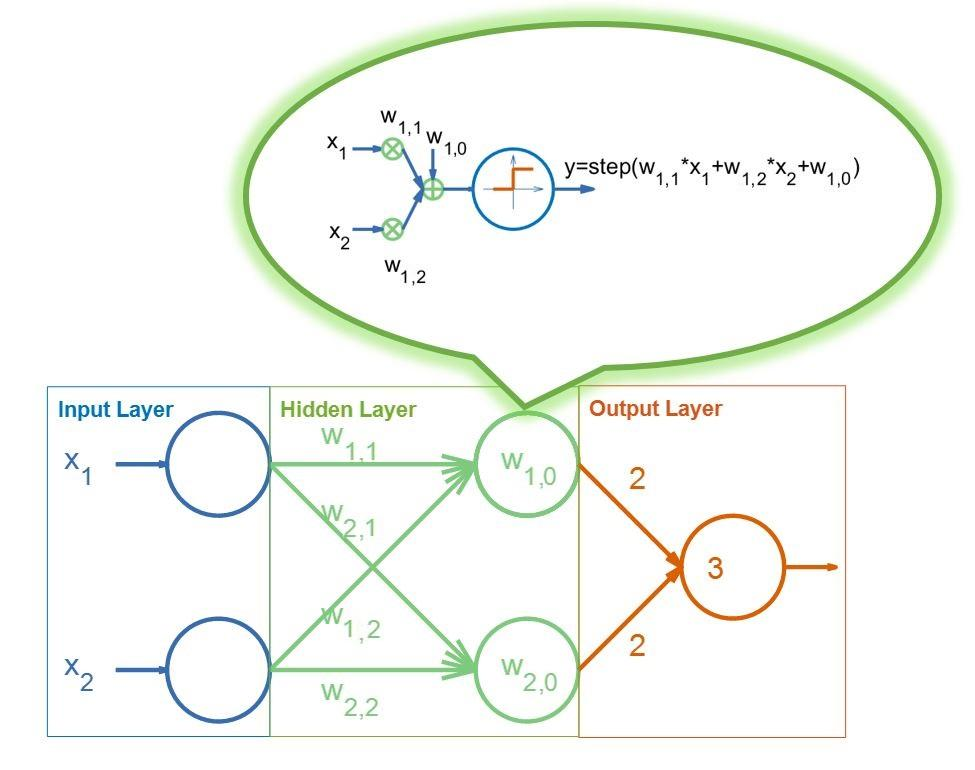

#### Exercise

Starting each time from the default parameters, train your neuron to learn the parameters that correctly classify the two implication functions $\left(x_1 \to x_2 \right)$ and $\left(x_2 \to x_1 \right)\ldotp$ Use these parameters in the `MultilayerDesigner` tab of the `Perceptron` app, to see the geometrical interpretation (parameters for the conjunction have already been given). 

For more clarity, the two separation lines for both implication functions and their vectors are shown in different styles:

- $\left(x_1 \to x_2 \right)$: continuous lines/vectors and circle markers 

- $\left(x_2 \to x_1 \right)$: dotted lines/vectors and cross markers.

Notice that the first neuron should fire for $\left(1,0\right)$, but not for $\left(0,1\right)$, while the other neuron behaves the other way around. The conjunction of the two implications will classify the training data correctly, the multilayer perceptron will only fire for $\left(0,0\right)$ and $\left(1,1\right)\ldotp$

The parameters learned starting from default values will have in both cases zero biases, which makes visualizing the boundaries separating the training data difficult. Use both the `SingleLayerDesignerTab` and the `SingleLayerOnlineLearningTab` to tweak your parameters (e.g., start by moving the bias from the origin) and improve the visualization. An example is given below:

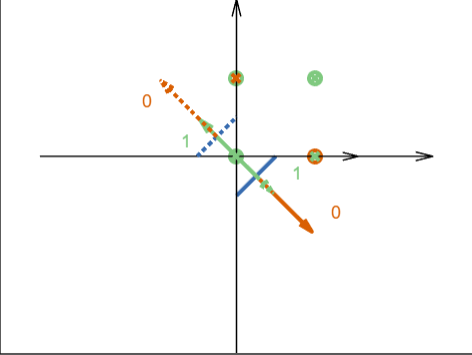

### Training of Neural Networks

We have seen that, even if perceptrons are limited in their modelling capabilities, they can be combined into networks that can model more complicated problems, e.g., when the training data is not linearly separable. A more complex problem requiring a network of perceptrons has nevertheless also a more complicated learning algorithm.

To illustrate this, we write the previously described three-layer network in a more general manner, like in the following figure:

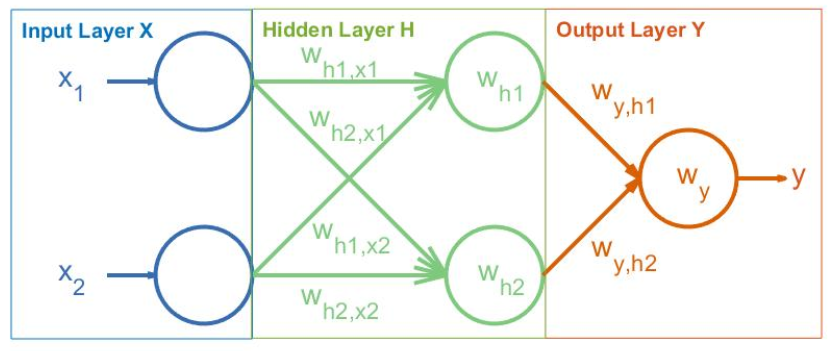 

The principle is the same as for the perceptron: we modify all weights to minimize an error function $e$ describing how well the actual outputs correspond to the desired outputs. For instance, we define the error function as $e=0\ldotp 5\sum_l {\left(y_l -o_l \right)}^2$, where $l$ iterates over the neurons in the output layer, $o_l$ are the actual outputs and $y_l$ the desired outputs.

We compute the error function for every training sample by **forward propagation**: we feed the training sample to the input layer and propagate it forward through the hidden layers to the output layer, to receive the actual output for the sample, and thus the error.

- Starting from a generic training sample and a continuously differentiable activation function (e.g., the sigmoid function $f\left(x\right)=1/\left(1+e^{-x} \right)$), we compute the actual outputs of the hidden layers $o_h \;$as follows:


$$o_h =f\left(\left\lbrack \begin{array}{ccc}
w_{h_1 x_1 }  & w_{h_1 x_2 }  & w_{h_1 } \\
w_{h_2 x_1 }  & w_{h_2 x_2 }  & w_{h_2 } 
\end{array}\right\rbrack \times \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
1
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
f\left(w_{h_1 x_1 } x_1 +w_{h_1 x_2 } x_2 +w_{h_1 } \right)\\
f\left(w_{h_2 x_1 } x_1 +w_{h_2 x_2 } x_2 +w_{h_2 } \right)
\end{array}\right\rbrack$$


- The two outputs of the hidden layers become inputs of the neuron in the output layer, whose actual output we compute as follows:


$$o_y =f\left(\left\lbrack \begin{array}{ccc}
w_{{\textrm{yh}}_1 }  & w_{{\textrm{yh}}_2 }  & w_y 
\end{array}\right\rbrack \times \left\lbrack \begin{array}{c}
o_{h_1 } \\
o_{h_2 } \\
1
\end{array}\right\rbrack \right)=f\left(w_{{\textrm{yh}}_1 } o_{h_1 } +w_{{\textrm{yh}}_2 } o_{h_2 } +w_y \right)$$


The error function is computed for the output layer, but depends on the weights of the neurons in all layers:


$$e=\frac{1}{2}{\left(y-o_y \right)}^2$$


In principle, we could try a brute force approach and compute the error function for every possible set of weights to find the optimal weights that would minimize the error function. Since this is not feasible, you can use the fact that the gradient (the vector of partial derivatives) of the error function indicates the rate of change (sensitivity) of the error function wrt the weights, and points into the direction into which the error function increases the fastest. Since we want to modify the weights to minimize the error, we can update the weights $w_i$ by taking a step in the opposite direction. The size of the step is the learning rate $\alpha$. 


$$\nabla_{w_i } e=\frac{\partial }{\partial w_i }e=\frac{1}{2}\sum_l \frac{\partial }{\partial w_i }\left(y_l -o_l \right)²=-\sum_l \left(y_l -o_l \right)\frac{\partial }{\partial w_i }o_l$$
 

- For the output layer, we can immediately update the weights, since we know the desired output for the neuron:


$$\Delta w_y =-\alpha \frac{\partial }{\partial w_y }e=-\frac{\alpha }{2}\frac{\partial }{\partial w_y }{\left(y-o_y \right)}^2 =\alpha \left(y-o_y \right)\frac{\partial }{\partial w_y }o_y =\alpha \left(y-f\left(w_{{\textrm{yh}}_1 } o_{h_1 } +w_{{\textrm{yh}}_2 } o_{h_2 } +w_y \right)\right)\frac{\partial }{\partial w_y }f\left(w_{{\textrm{yh}}_1 } o_{h_1 } +w_{{\textrm{yh}}_2 } o_{h_2 } +w_y \right)$$


- For the hidden layer, the training data does not specify a desired output to compare with the actual output, like for neuron in the output layer; however, since the actual outputs $o_h$ are the inputs of the neuron in the output layer, for which we know the desired output and the error, we can apply the chain rule to update the weights. This is called **backward propagation**. 


$$\Delta w_{h_1 x_1 } =-\alpha \frac{\partial }{\partial w_{h_1 x_1 } }e=-\frac{\alpha }{2}\frac{\partial }{\partial w_{h_1 x_1 } }{\left(y-o_y \right)}^2 =\alpha \left(y-o_y \right)\frac{\partial }{\partial w_{h_1 x_1 } }o_y$$



$$\textrm{where}\;\;\frac{\partial }{\partial w_{h_1 x_1 } }o_y =\frac{\partial }{\partial o_{h_1 } }o_y \;\frac{\partial }{\partial w_{h_1 x_1 } }o_{h_1 }$$


The three-layer network modelling the biimplication is an example of a shallow neural network. If a neural network has more "hidden layers" of neurons, it is a deep neural network:

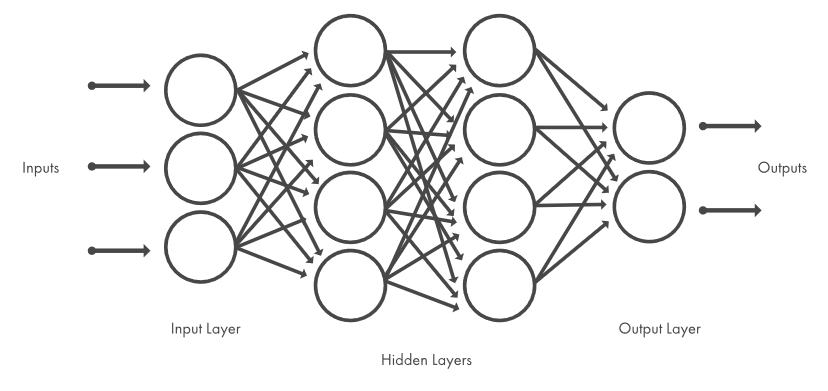

A neural network, no matter how simple or complex, is ultimately just a mathematical function that takes inputs and returns outputs. The way inputs are mapped to outputs is the **network architecture**. When you **train a network**, you use inputs and outputs in your **training data set** to determine the values of the **network parameters, **by looking for the parameters that minimize the error between computed and known outputs. For a neural network to be used for real-world applications, such as for automated driving, the network should be trained on large training data sets with hundreds, thousands or even millions of data samples. 

The mathematics can become quite messy. MATLAB makes deep learning easy with specialized tools and functions that let us apply deep learning techniques also without being experts. We can create and visualize models with just a few lines of code, and we can integrate AI into the complete workflow for developing a fully engineered system, for many types of data, e.g., images, signals, time series, text.

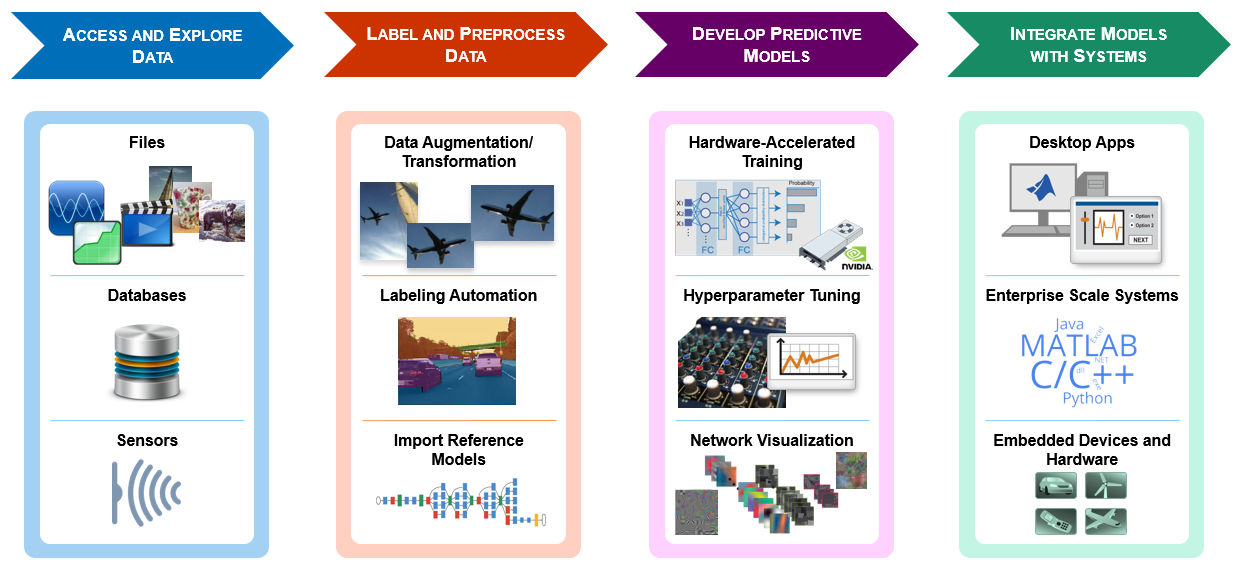

### Learn More

[Deep Learning Onramp](https://www.mathworks.com/learn/tutorials/deep-learning-onramp.html) - free two-hour tutorial providing an introduction to practical deep learning techniques for image recognition.

[Deep Learning with MATLAB](https://matlabacademy.mathworks.com/R2020a/portal.html?course=mldl&s_tid=sched_leaf_spot) - comprehensive introduction to practical deep learning techniques.

[AI with MATLAB](https://www.mathworks.com/campaigns/offers/ai-with-matlab.html)

**Author: Mihaela Jarema, mjarema@mathworks.com, release R2020a.**